%Set up parameters and initial conditions: 
k1 = 5.7; k2 = 6.1;
c0 = [4.0; 1.0; 0.5; 0.0];
tspan = linspace(0, 2, 100); %constant time step

%Solve ODE:
dCdt = @(t, C) [
    -k1 * C(1)
     k2 * C(1) - k2 * C(2)
     k2 * C(2)
     k1 * C(1) + k2 * C(2)
];
[t, C] = ode45(dCdt, tspan, c0)

t =          0
    0.0202
    0.0404
    0.0606
    0.0808
    0.1010
    0.1212
    0.1414
    0.1616
    0.1818
    0.2020
    0.2222
    0.2424
    0.2626
    0.2828


C =     4.0000    1.0000    0.5000         0
    3.5649    1.3216    0.6440    0.5791
    3.1772    1.5584    0.8222    1.1450
    2.8316    1.7254    1.0250    1.6935
    2.5236    1.8350    1.2450    2.2214
    2.2491    1.8982    1.4756    2.7265
    2.0045    1.9243    1.7113    3.2069
    1.7864    1.9206    1.9484    3.6619
    1.5921    1.8932    2.1836    4.0915
    1.4190    1.8477    2.4145    4.4955
    1.2646    1.7887    2.6386    4.8740
    1.1270    1.7198    2.8547    5.2277
    1.0044    1.6438    3.0620    5.5576
    0.8952    1.5629    3.2597    5.8645
    0.7979    1.4795    3.4474    6.1495



dt = diff(t);
dxdt = diff(C)./dt;

%Train model to map xt -> dxdt
X = C(1:end-1,:);
Y = dxdt;
arraySize = [12 4];

rng("default") 
c = cvpartition(length(Y),"Holdout",0.20);
trainingIdx = training(c); 
XTrain = X(trainingIdx,:);
YTrain = Y(trainingIdx,:);
testIdx = test(c);
XTest = X(testIdx,:);
YTest = Y(testIdx,:);
modelNN2 = fitrnet(X,Y,"Standardize",false, ...
    "LayerSizes", arraySize)

modelNN2 =   RegressionNeuralNetwork
             ResponseName: {'y1'  'y2'  'y3'  'y4'}
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 99
               LayerSizes: [12 4]
              Activations: 'relu'
    OutputLayerActivation: 'none'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [1000×7 table]


  Properties, Methods



lossNN2 = loss(modelNN2, XTest, YTest)

lossNN2 = 1.1751e-04

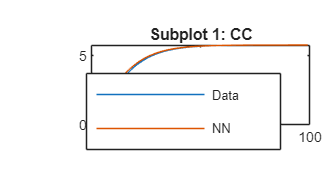

%Forward pass to validate results:
fNN = zeros(100-1, 4);
fNN(1, :) = C(1, :);
for i = 1:(100-1)
    % fNN(i,:) = C(i, :) + dt(i) .* predict(modelNN2, C(i+1, :));
    fNN(i+1,:) = fNN(i, :) + dt(i) .* predict(modelNN2, fNN(i, :));
end

%Plot to check results
%Plot result: COMPARE Raw Data to NN:
figure
hold on
p = tiledlayout(2,2);
ptitles = ['Subplot 1: CA'
    'Subplot 1: CB'
    'Subplot 1: CC'  
    'Subplot 1: CD'];
for i = 1:4
    nexttile;
    plot([fNN(1:99,i), C(2:100,i)])
    legend('Data', 'NN')
    title(ptitles(i, :))
end 
hold off

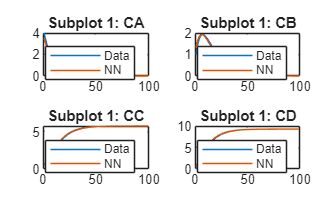

%Explicit Euler to validate results:
fNN = zeros(100-1, 4);
fNN(1, :) = C(1, :);
for i = 1:(100-1)
    xstd = fNN(i, :);
    z1 = modelNN2.LayerWeights{1} * xstd' + modelNN2.LayerBiases{1};
    z1 = max(0, z1);
    z2 = modelNN2.LayerWeights{2} * z1 + modelNN2.LayerBiases{2};
    z2 = max(0, z2);
    z3 =  modelNN2.LayerWeights{3} * z2 + modelNN2.LayerBiases{3};
    fNN(i+1, :) = fNN(i, :) + dt(i) .* z3';
end 

%Plot to check results
%Plot result: COMPARE Raw Data to NN:
figure
hold on
p = tiledlayout(2,2);
ptitles = ['Subplot 1: CA'
    'Subplot 1: CB'
    'Subplot 1: CC'  
    'Subplot 1: CD'];
for i = 1:4
    nexttile;
    plot([fNN(1:99,i), C(2:100,i)])
    legend('Data', 'NN')
    title(ptitles(i, :))
end 
hold off

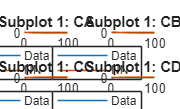

%Explicit Euler to validate results:

fNN = zeros(100-1, 4);
fNN(1, :) = C(1, :);
for i = 1:(100-1)
    xstd = (fNN(i, :) - modelNN2.Mu)./ modelNN2.Sigma;
    z1 = modelNN2.LayerWeights{1} * xstd' + modelNN2.LayerBiases{1};
    z1 = max(0, z1);
    z2 = modelNN2.LayerWeights{2} * z1 + modelNN2.LayerBiases{2};
    fNN(i+1, :) = fNN(i, :) + dt(i) .* z2';
end 

%Plot to check results
%Plot result: COMPARE Raw Data to NN:
figure
hold on
p = tiledlayout(2,2);
ptitles = ['Subplot 1: CA'
    'Subplot 1: CB'
    'Subplot 1: CC'  
    'Subplot 1: CD'];
for i = 1:4
    nexttile;
    plot([fNN(1:99,i), C(2:100,i)])
    legend('Data', 'NN')
    title(ptitles(i, :))
end 
hold off

%Forward PASS
predict(modelNN2, C(1, :))

ans =   -19.1939   11.7189    8.8219   28.0159



xstd = (C(1,:) - modelNN2.Mu) ./ modelNN2.Sigma;
z1 = modelNN2.LayerWeights{1} * xstd' + modelNN2.LayerBiases{1};
z1 = max(0, z1);
z2 = modelNN2.LayerWeights{2} * z1 + modelNN2.LayerBiases{2};
z2 = max(0, z2);
z3 = modelNN2.LayerWeights{3} * z2 + modelNN2.LayerBiases{3}

z3 =   -19.1939
   11.7189
    8.8219
   28.0159


modelNN2.Mu

ans =     0.3715    0.4375    4.9456    8.0742


modelNN2.Sigma

ans =     0.8089    0.6247    1.4074    2.1958


filename = "FitRNet_Storage_RawData.xlsx";
writematrix(C, filename,'Sheet', 1, 'Range', 'A1')

filename = "FitRNet_Storage_THETA.xlsx";
for i = 1:length(modelNN2.LayerSizes)+1
    writematrix(modelNN2.LayerWeights{i}, filename,'Sheet', i, 'Range', 'A1')
end %for 

filename = "FitRNet_Storage_CCOEFF.xlsx";
for i = 1:length(modelNN2.LayerSizes)+1
    writematrix(modelNN2.LayerBiases{i}, filename,'Sheet', i, 'Range', 'A1')
end %for 